## Example: Descriptive Statistics and Data Visualisation

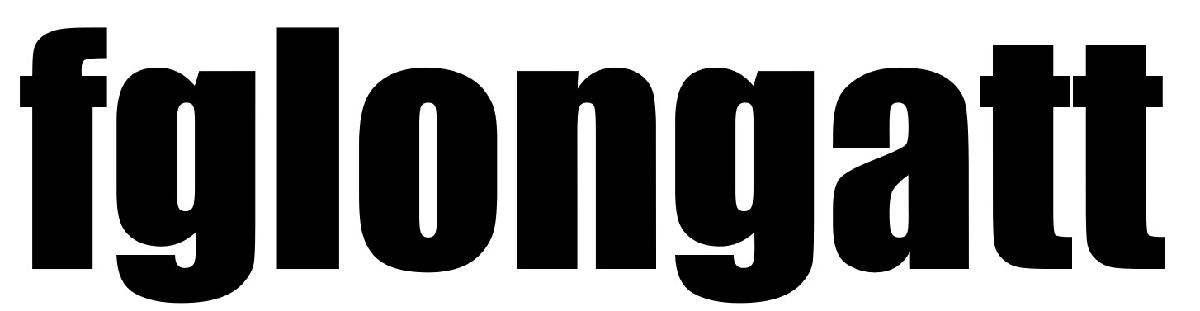  F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

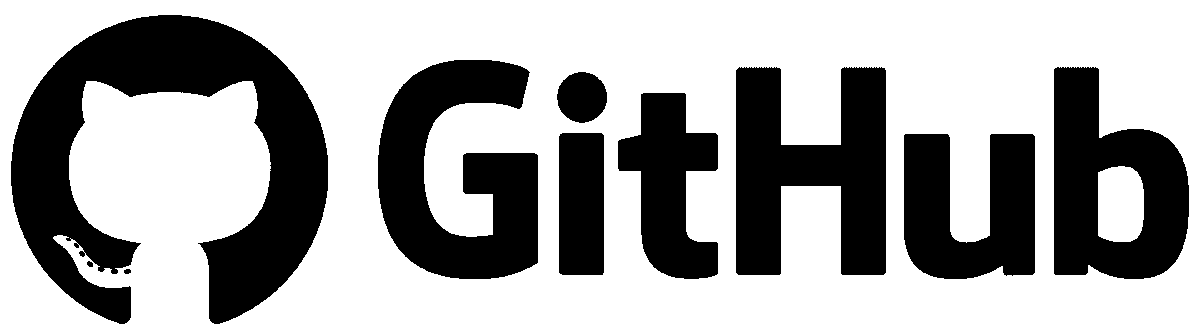 [https://github.com/fglongatt](https://github.com/fglongatt) 

clc
clearvars
% Read data from a file
FILENAME = 'Carbon_Intensity_Gen_Mix_2009-2025.csv';
data = readtable(FILENAME);
% disp(data)
% Select data of the column 3
data(1:3,:)

ans = 3×32 table
        DATETIME        GAS     COAL     NUCLEAR    WIND    HYDRO    IMPORTS    BIOMASS    OTHER    SOLAR    STORAGE    GENERATION    CARBON_INTENSITY    LOW_CARBON    ZERO_CARBON    RENEWABLE    FOSSIL    GAS_perc    COAL_perc    NUCLEAR_perc    WIND_perc    HYDRO_perc    IMPORTS_perc    BIOMASS_perc    OTHER_perc    SOLAR_perc    STORAGE_perc    GENERATION_perc    LOW_CARBON_perc    ZERO_CARBON_perc    RENEWABLE_perc    FOSSIL_perc
 

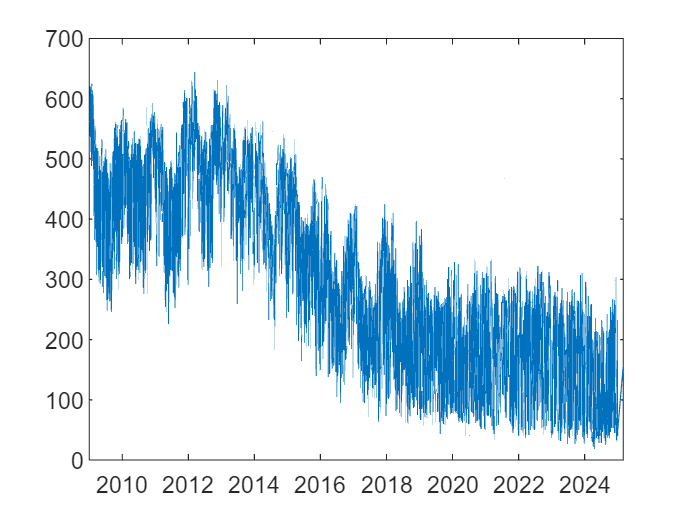

Tiempo = data.DATETIME;
Data1 = data.CARBON_INTENSITY;
DataGAS = data.GAS;
DataWIND = data.WIND;
DataSOLAR = data.SOLAR;

% Plot data
plot(Tiempo,data.CARBON_INTENSITY)

## I. Descriptive Statistics 

mean_value = mean(Data1);
fprintf(' Mean = %4.4f',mean_value)

 Mean = 302.0406

mode_value = mode(Data1);
fprintf(' Mode = %4.4f',mode_value)

 Mode = 208.0000

median_value = median(Data1);
fprintf(' Mode = %4.4f',median_value)

 Mode = 273.0000

% Calculate the variance
variance_value = var(Data1);
fprintf(' Variance = %4.4f',variance_value)

 Variance = 21633.3620

% Calculate the standard deviation
std_value = std(Data1);
fprintf(' Standard Deviation = %4.4f',std_value)

 Standard Deviation = 147.0828

% Calculate the maximum
max_value = max(Data1);
% Calculate the minimum
min_value = min(Data1);
% Calculate the interquartile range (IQR)
iqr_value = iqr(Data1);
% Display the results
fprintf('Maximum: %4.4f ', max_value);

Maximum: 644.0000 

fprintf('Minimum: %4.4f',min_value);

Minimum: 19.0000

fprintf('Interquartile Range: %4.4f',iqr_value);

Interquartile Range: 257.0000

## II. Data Visualization

Data visualization is the graphical representation of information and data. By using visual elements like charts, graphs, and maps, data visualization tools provide an accessible way to see and understand trends, outliers, and patterns in data.

### Scatter Plots

A scatter plot is a type of data visualization that displays values for typically two variables as a collection of points. Each point represents an observation in the dataset, with its position determined by the values of the two variables.

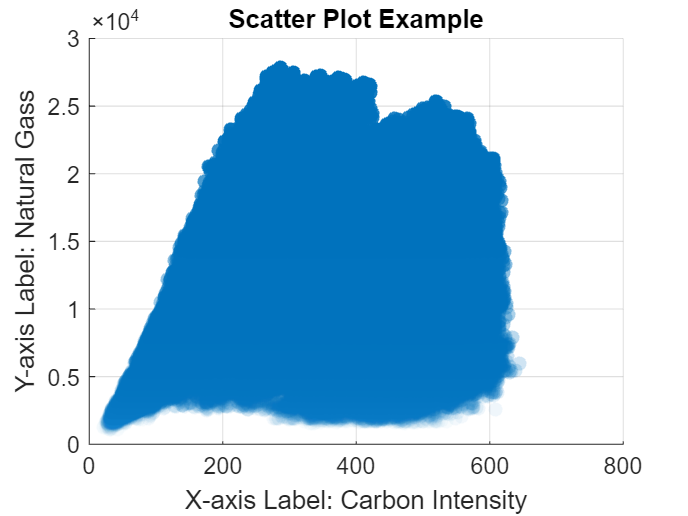

% Data can be changed as interest here, x and y.
figure;
x = Data1;
y = DataGAS;
s = scatter(x,y,'filled');
% Add labels and title
xlabel('X-axis Label: Carbon Intensity');
ylabel('Y-axis Label: Natural Gass');
title('Scatter Plot Example');
% Customize the appearance (optional)
grid on; % Add grid lines
distfromzero = sqrt(x.^2 + y.^2);
s.AlphaData = distfromzero;
s.MarkerFaceAlpha = 'flat';

### Histogram

A histogram is a graphical representation used to display the distribution of a dataset. It consists of rectangular bars (bins) that represent the frequency of data points within specific ranges or intervals.

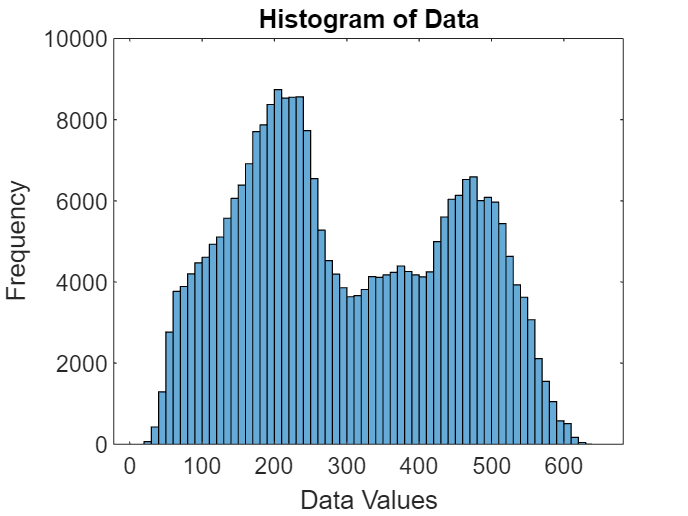

% Calculate and plot the histogram
histogram(Data1);
% Add labels and title
xlabel('Data Values');
ylabel('Frequency');
title('Histogram of Data');

### Boxplot

A boxplot, also known as a box-and-whisker plot, is a standardized way of displaying the distribution of data based on a five-number summary: minimum, first quartile (Q1), median, third quartile (Q3), and maximum. It provides a visual representation of the central tendency, spread, and variability of a dataset.

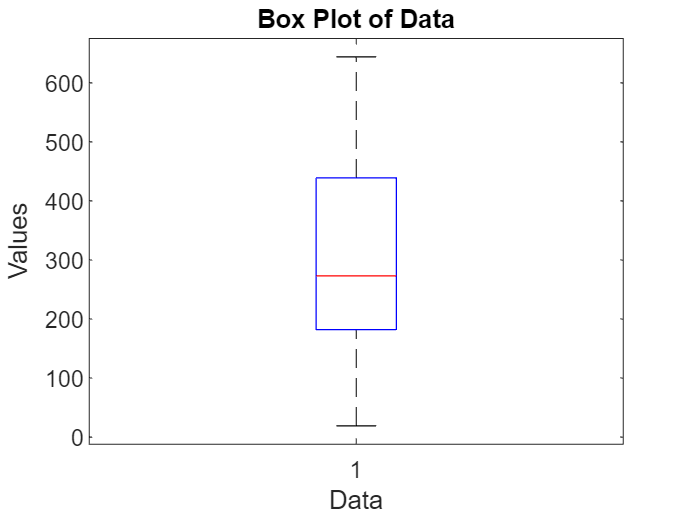

% Create the box plot
boxplot(Data1);
% Add labels and title
xlabel('Data');
ylabel('Values');
title('Box Plot of Data');

### Duration Curve

A duration curve is a graphical representation used primarily in hydrology, power systems, and other fields to show the distribution of a certain variable over time. It displays the relationship between the magnitude of the variable (e.g., streamflow, power generation) and the percentage of time that the variable is equaled or exceeded.

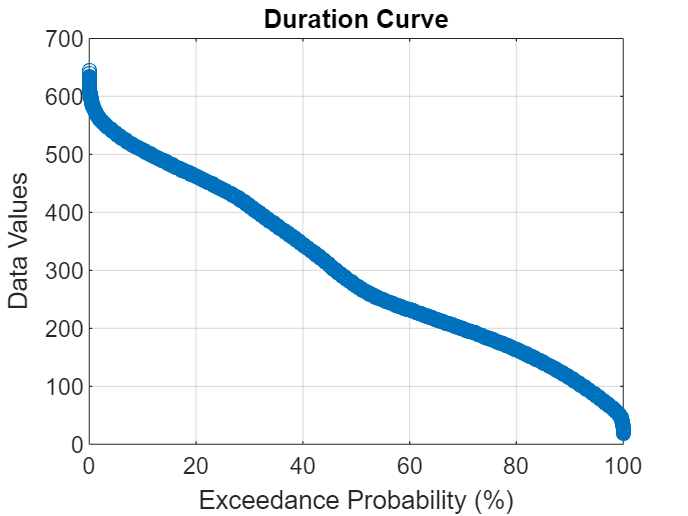

% Sort the data in descending order
sorted_data = sort(Data1, 'descend');
% Calculate exceedance probability
exceedance_probability = (1:length(sorted_data)) / length(sorted_data);
% Plot the duration curve
figure;
plot(exceedance_probability * 100, sorted_data, '-o');
% Add labels and title
xlabel('Exceedance Probability (%)');
ylabel('Data Values');
title('Duration Curve');
grid on;

### Probabilistic Density Function (PDF)

A probability density function (PDF) is a statistical function that describes the likelihood of a continuous random variable taking on a particular value. Unlike the probability mass function (PMF) used for discrete random variables, the PDF is used for continuous data and indicates the relative likelihood of the variable falling within a specific range of values.

The `ksdensity` function is used to perform kernel density estimation and calculate the PDF. 

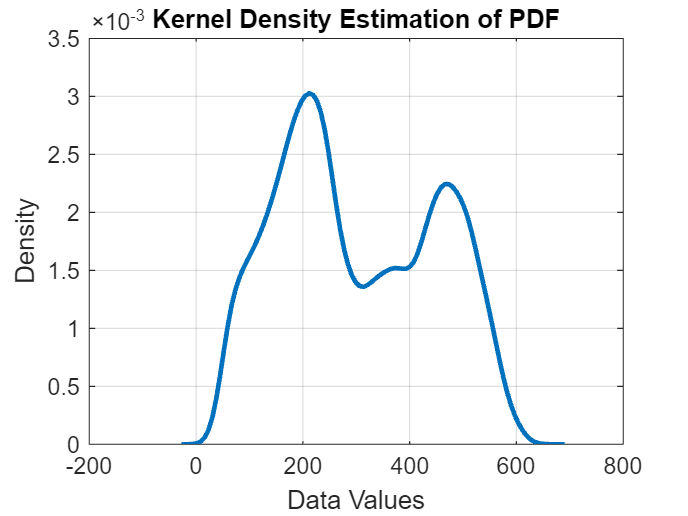

% Estimate the PDF using kernel density estimation
[f, xi] = ksdensity(Data1);
% Plot the estimated PDF
figure;
plot(xi, f, 'LineWidth', 2);
xlabel('Data Values');
ylabel('Density');
title('Kernel Density Estimation of PDF');
grid on;

Slicing data over per one year

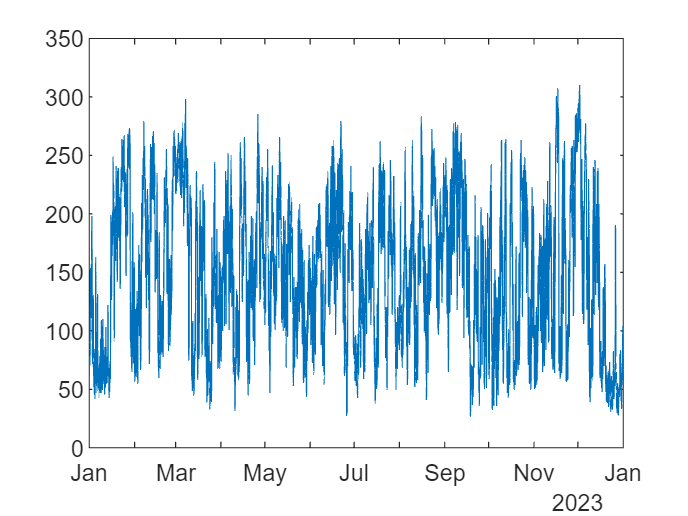

year_of_interest = 2023;
filtered_data = data(year(data.DATETIME) == year_of_interest, :);
plot(filtered_data.DATETIME,filtered_data.CARBON_INTENSITY)

Boxplot considering the grouping per motnh using datetime

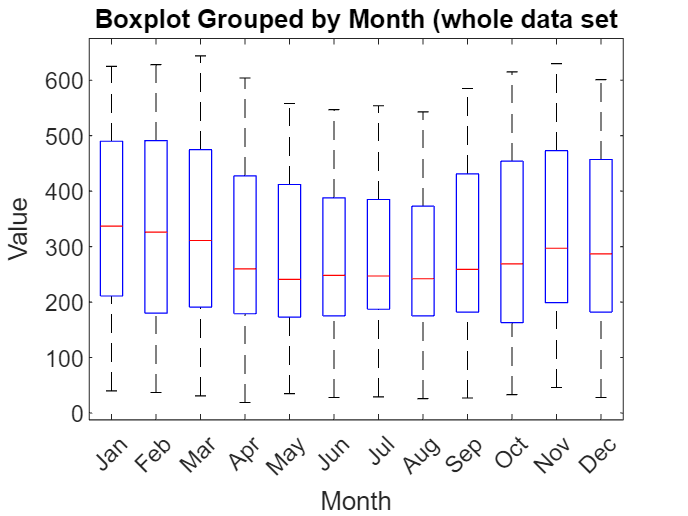

% Extract the month from the datetime column
data.Month = month(data.DATETIME);
% Create the boxplot grouped by Month
boxplot(data.CARBON_INTENSITY, data.Month);
% Customize the plot
xlabel('Month');
ylabel('Value');
title('Boxplot Grouped by Month (whole data set');
% Optional: Adjust x-axis for month labels
xticks(1:12); % Ensure 12 ticks for months
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', ...
             'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'});

Boxplot considering the grouping per week days using datetime

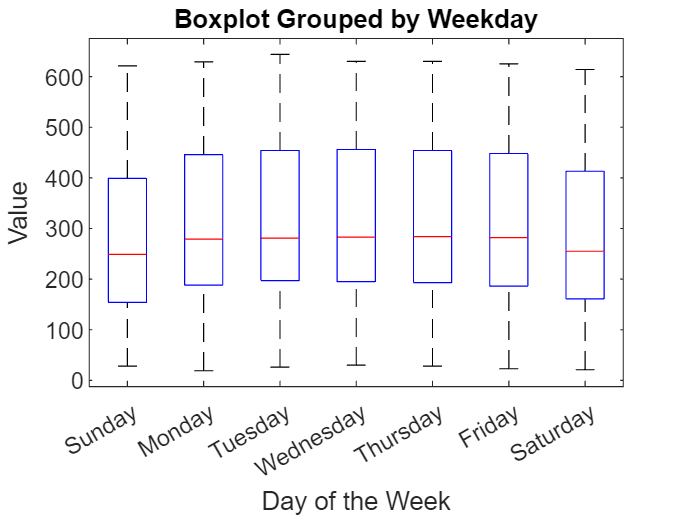


% Extract the day of the week as a grouping variable
% Extract the numeric representation of the weekday (1 = Sunday, ..., 7 = Saturday)
weekday_numeric = weekday(data.DATETIME);

% Create the boxplot grouped by the numeric weekday
boxplot(data.CARBON_INTENSITY, weekday_numeric);

% Customize the plot
xlabel('Day of the Week');
ylabel('Value');
title('Boxplot Grouped by Weekday');

% Replace numeric weekday ticks with weekday names
xticks(1:7); % Ensure 7 ticks for weekdays
xticklabels({'Sunday', 'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday'});

Boxplot considering the grouping per hour using datetime

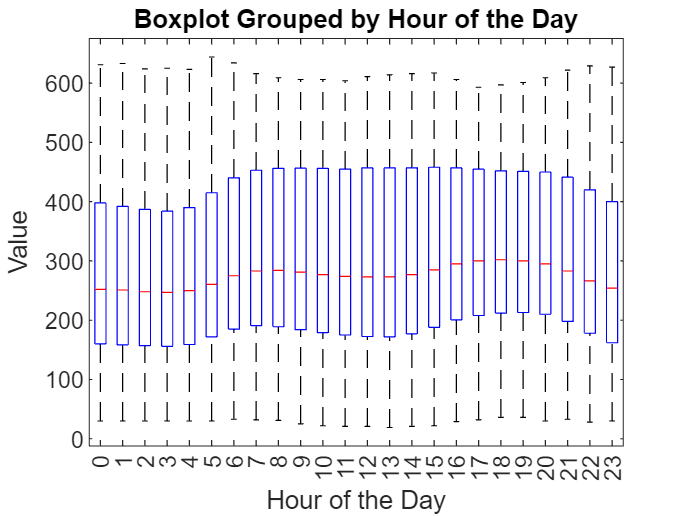

x = data.DATETIME;
y = data.CARBON_INTENSITY;
% Extract the hour as a numeric variable
hour_numeric = hour(x);
% Create the boxplot grouped by hour
boxplot(y, hour_numeric);
% Customize the plot
xlabel('Hour of the Day');
ylabel('Value');
title('Boxplot Grouped by Hour of the Day');

Plotting correlation matrix using heatmap. 

x = data.CARBON_INTENSITY

x =    525
   526
   527
   527
   528
   529
   531
   531
   534
   535


y = data.GAS

y =         8378
        8510
        8484
        8328
        8303
        8312
        8363
        8314
        8543
        8804


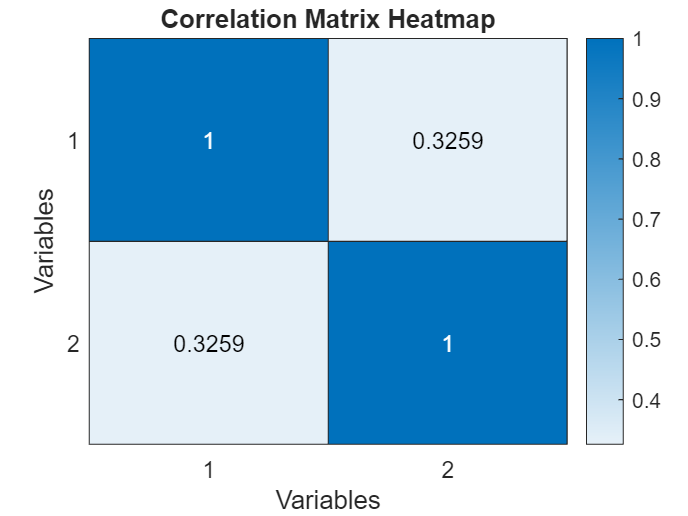

data = [x y];
correlation_matrix = corr(data);
% Plot the correlation matrix using a heatmap
heatmap(correlation_matrix);
% Customize the plot
xlabel('Variables');
ylabel('Variables');
title('Correlation Matrix Heatmap');

Be part of our community 

 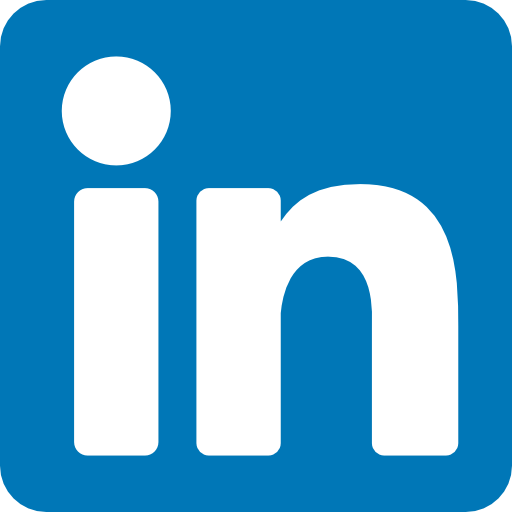 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 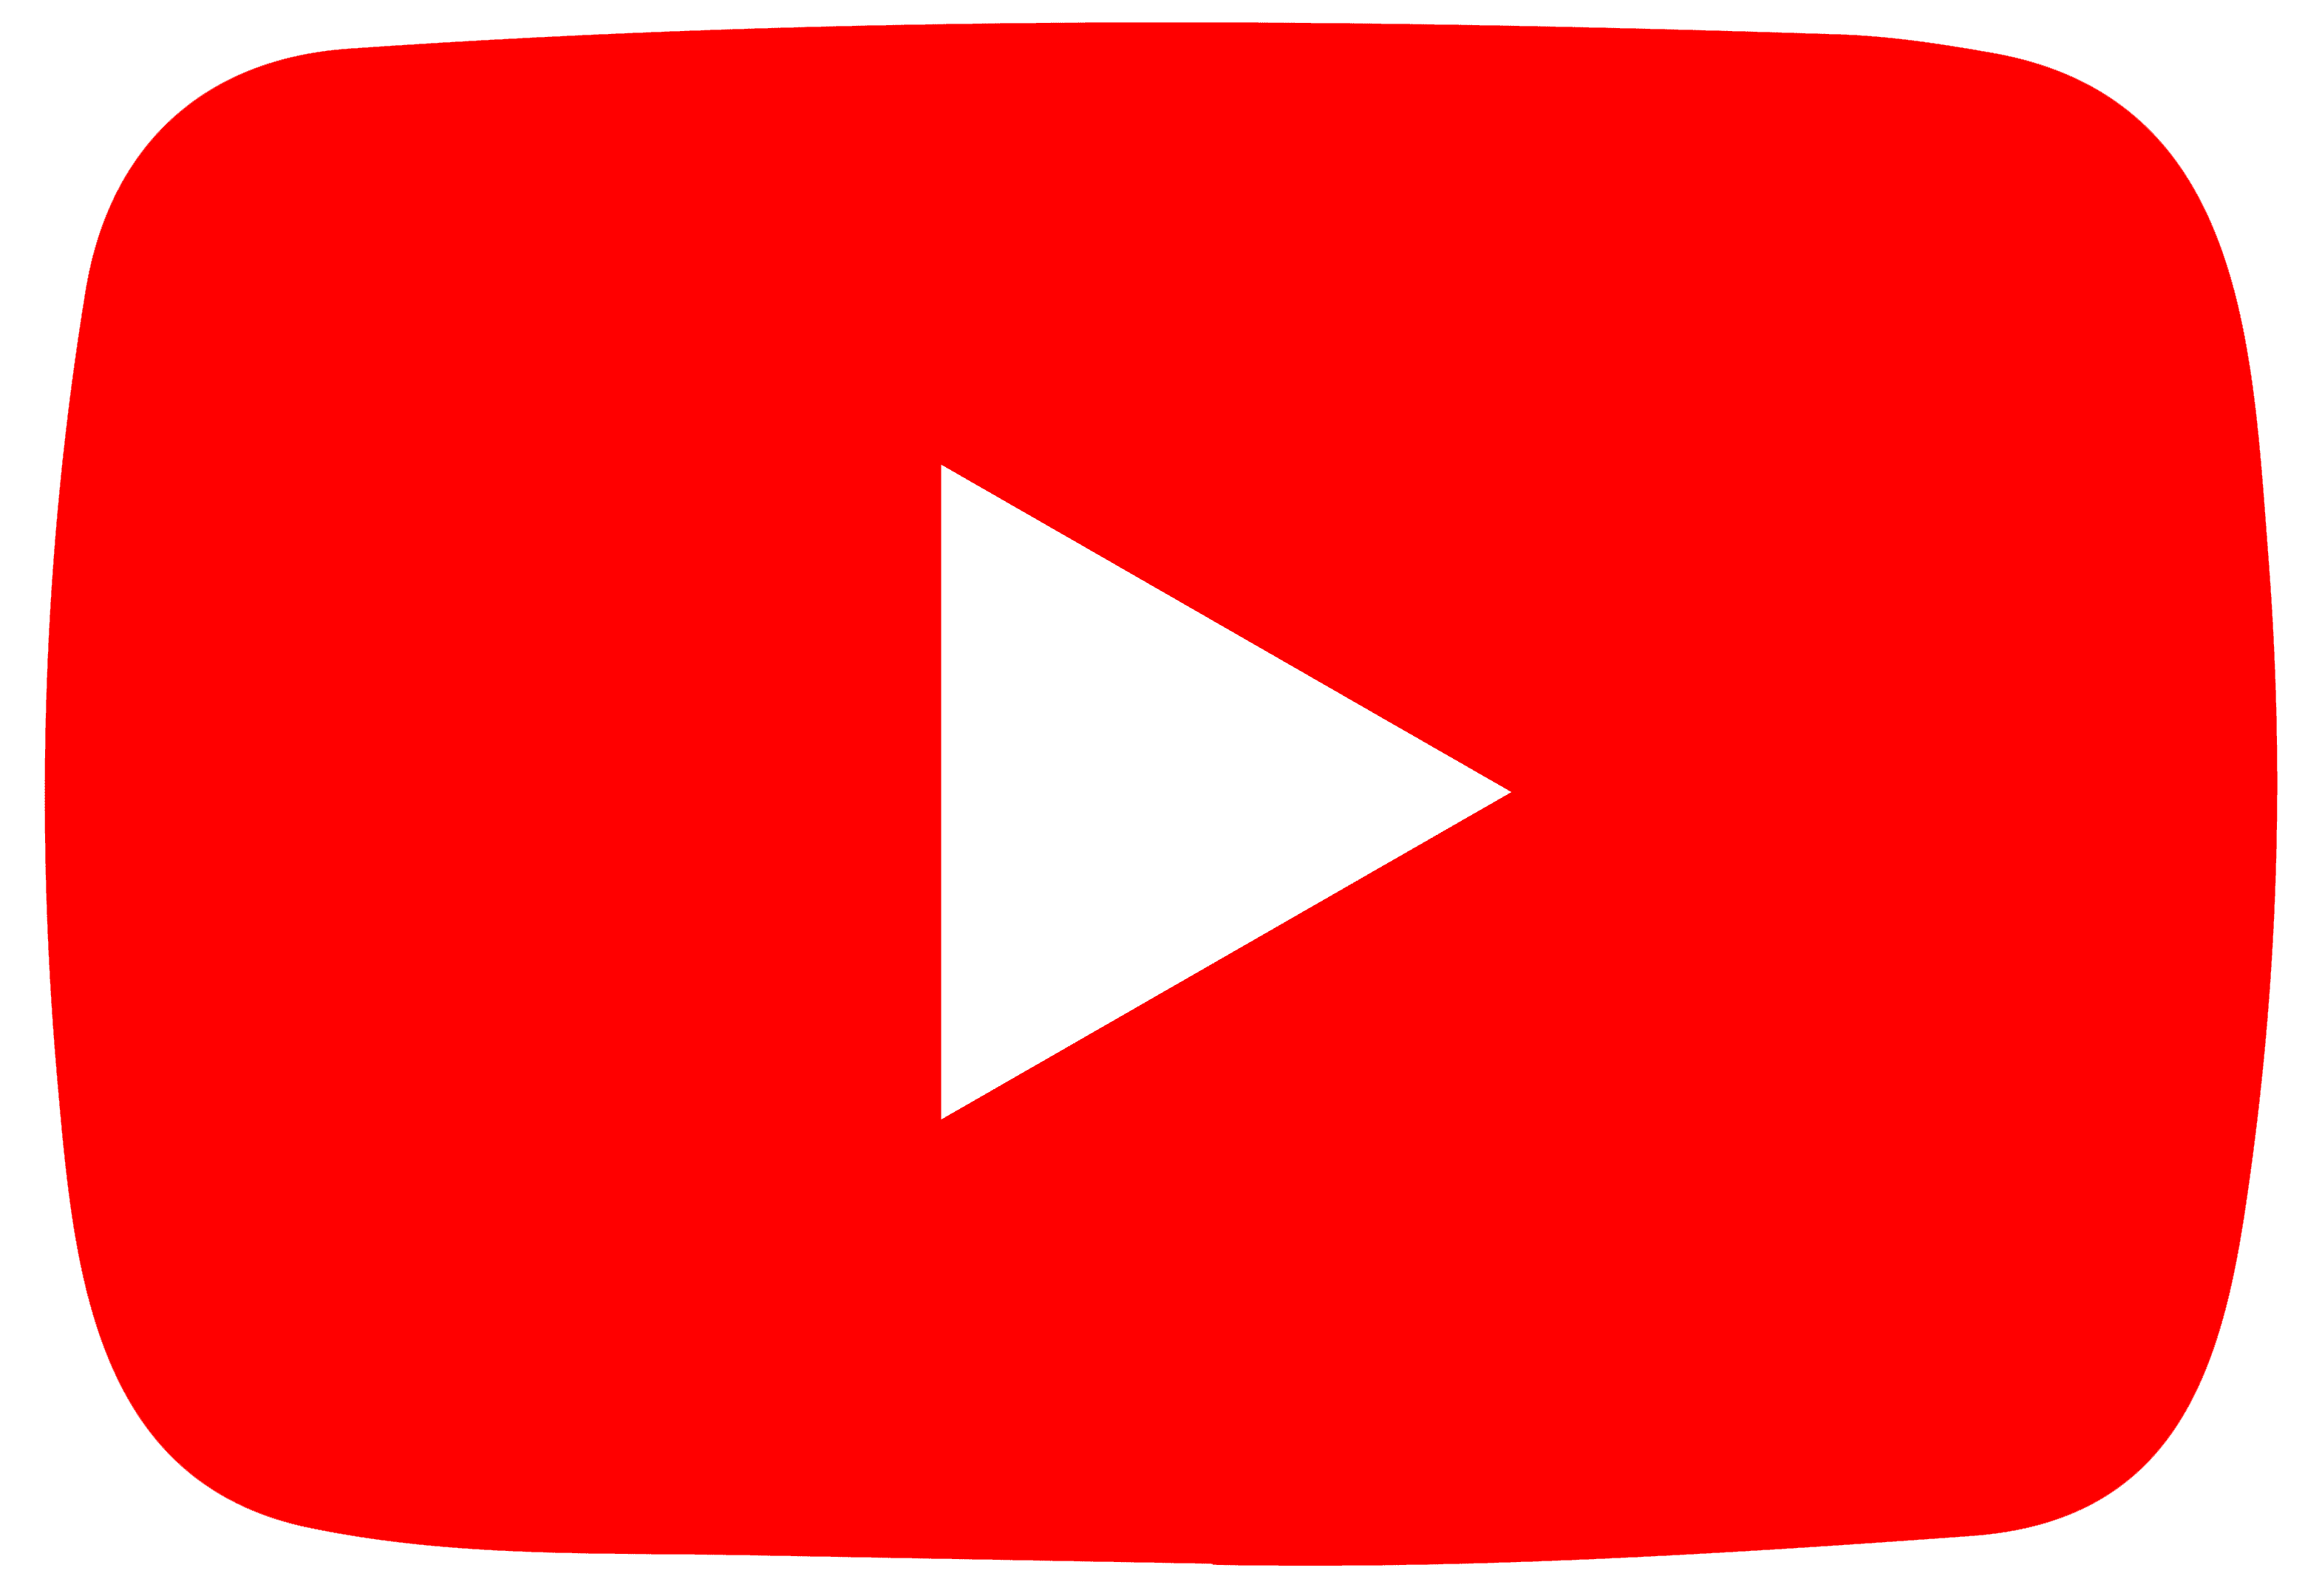 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

 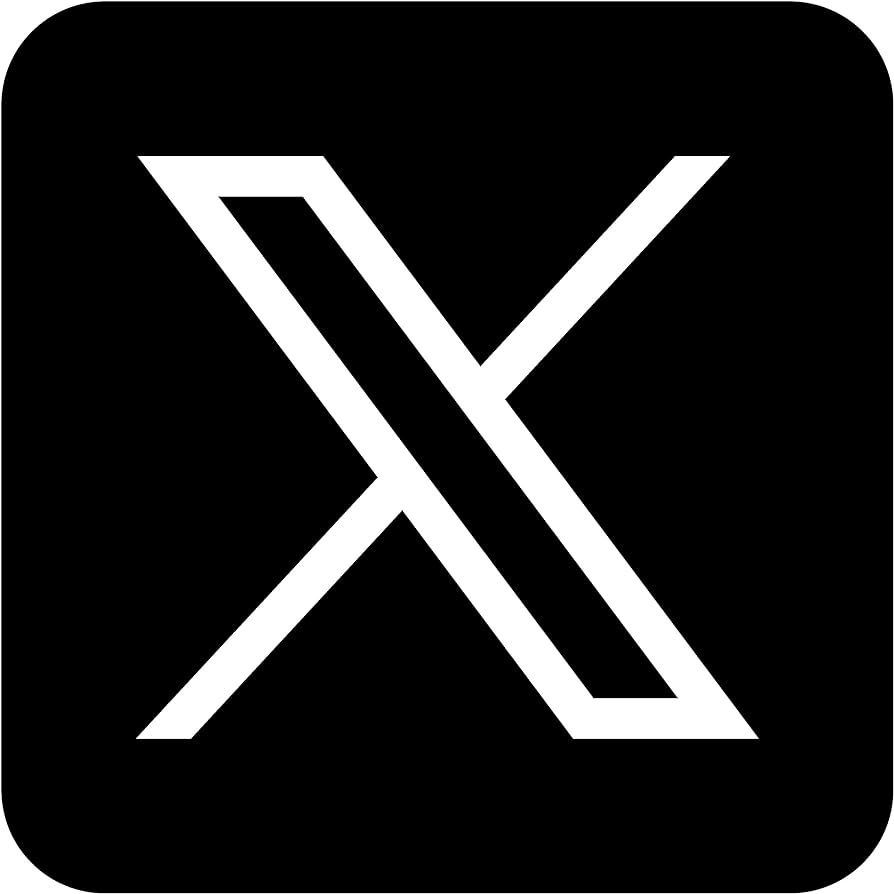  [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

 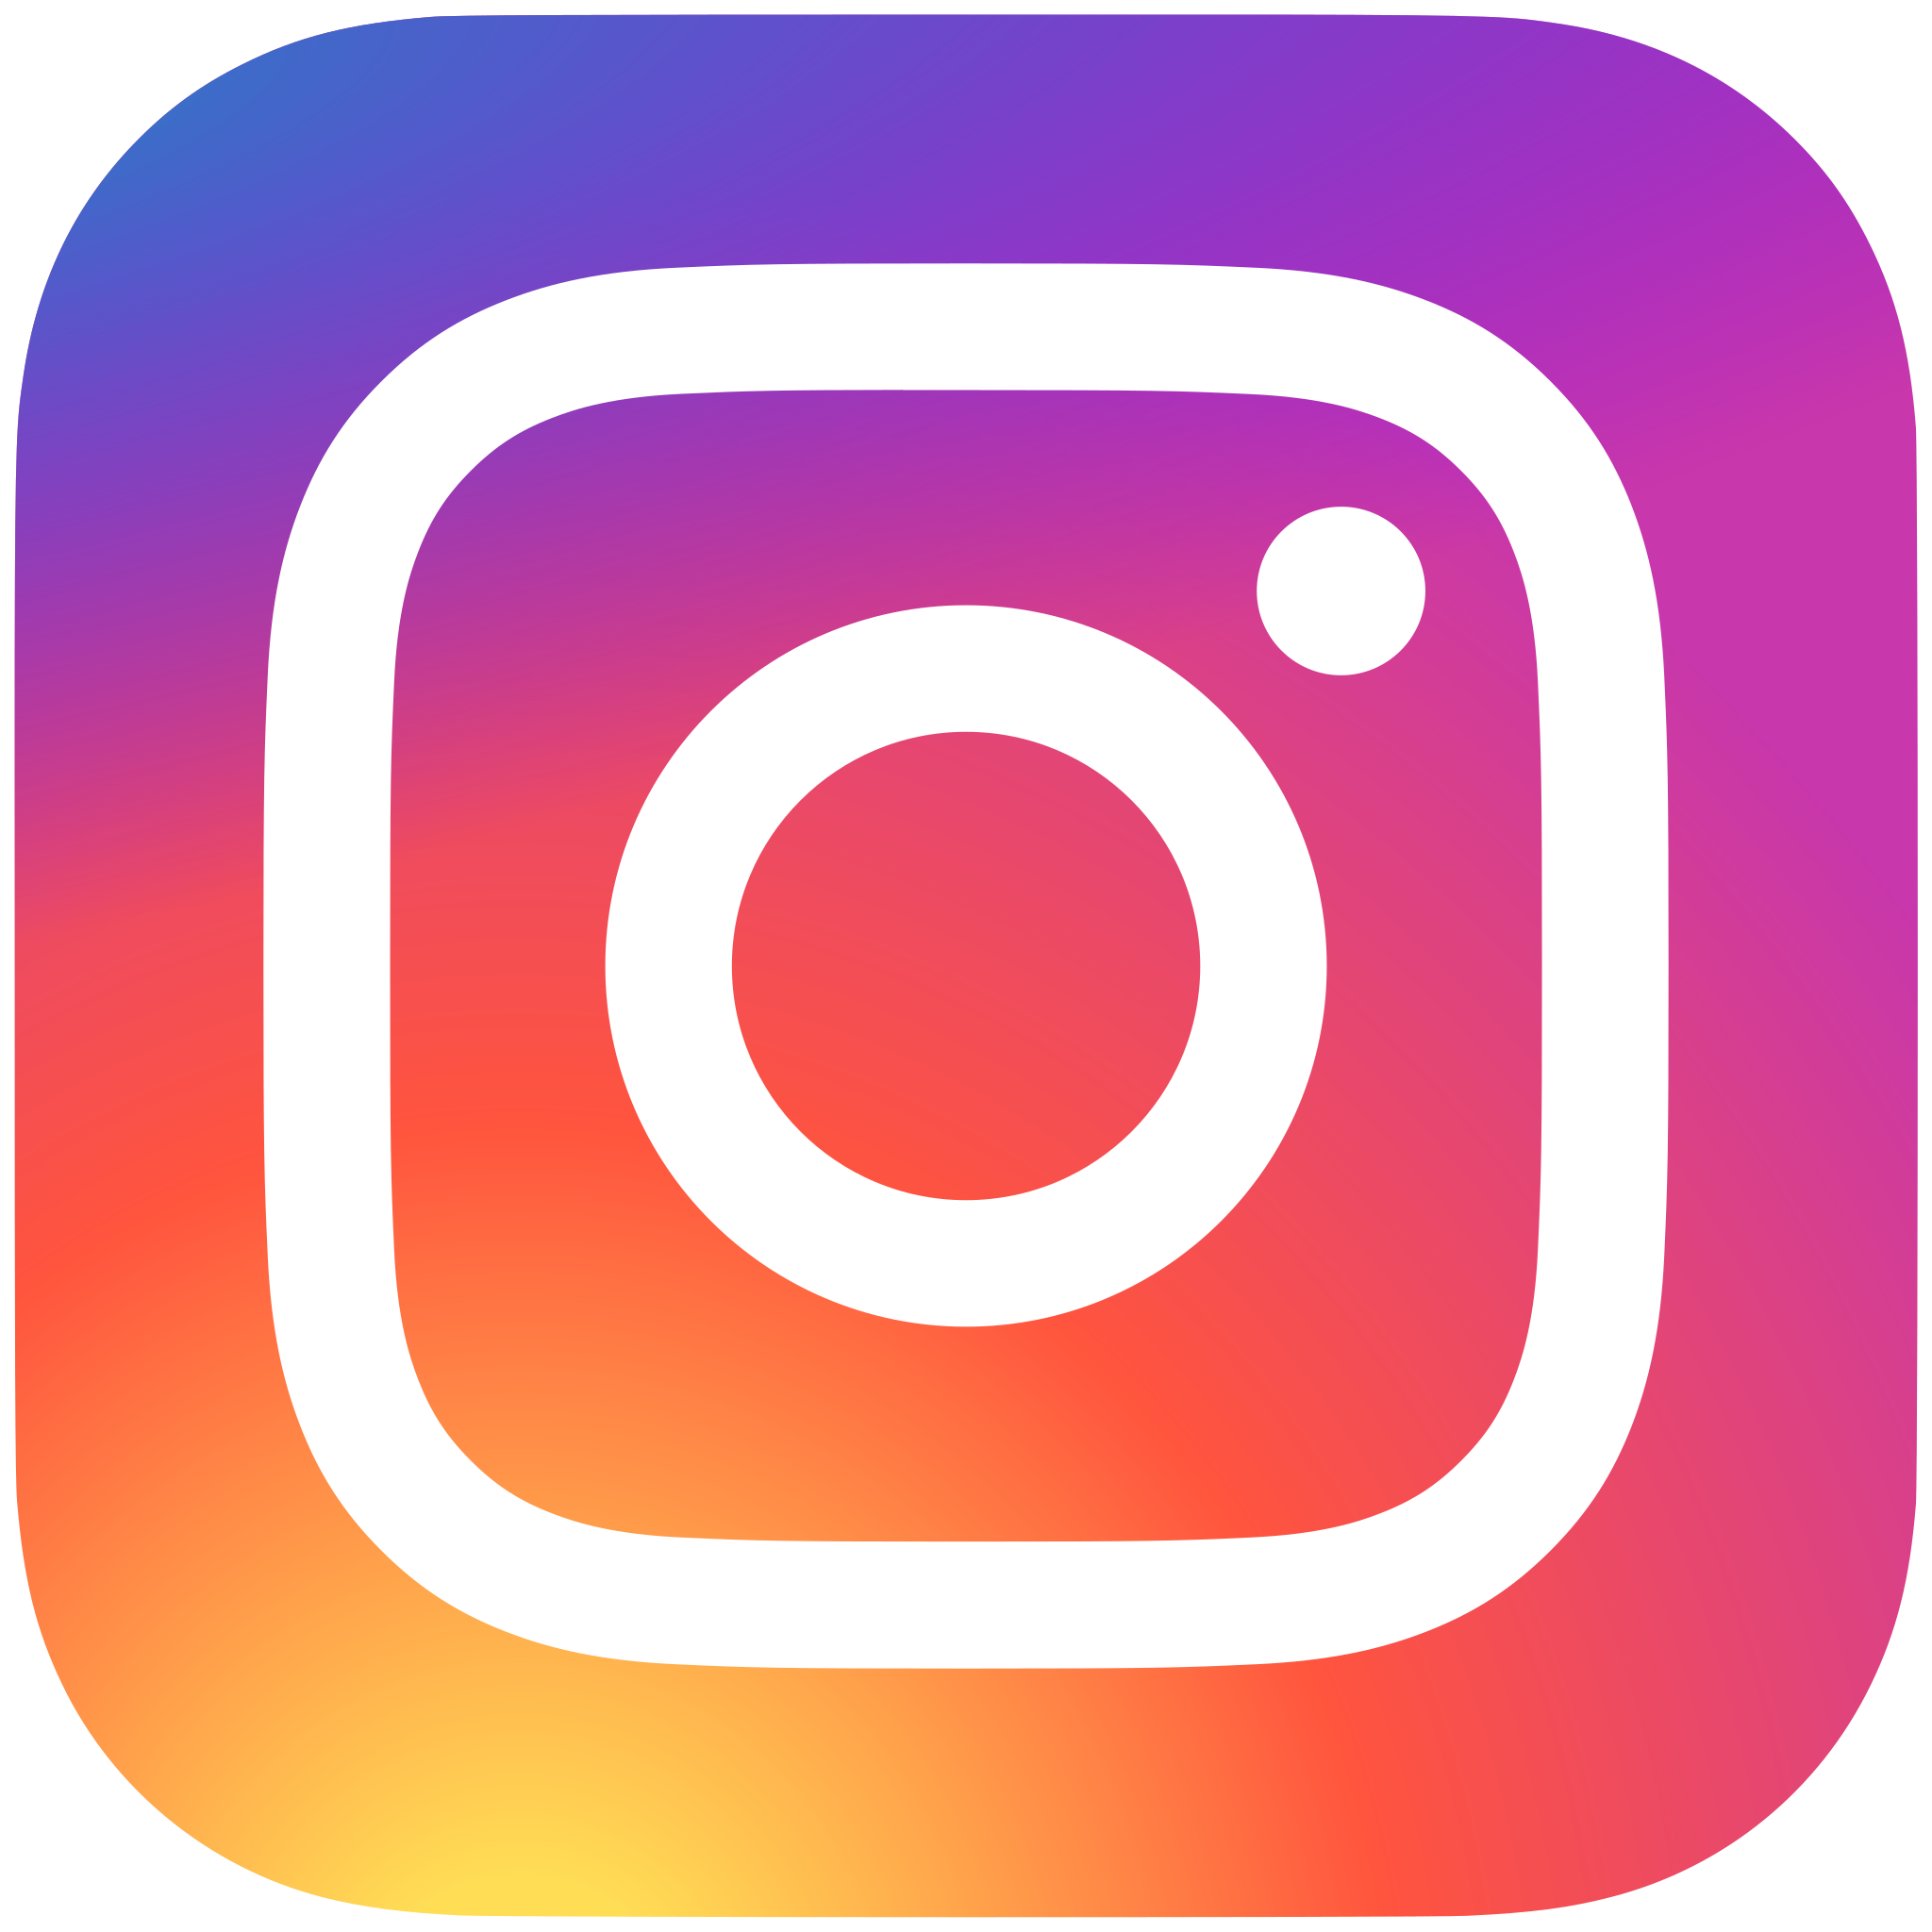 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 